clc;clear;
workingpath='/Volumes/WD_D/gufei/monkey_data/campwater_newmonkey';
cd(workingpath);

files=dir('*side.csv');
alldata=cell(1,length(files));
% middle point
m=zeros(1,length(files));
conditions=cell(1,length(files));
for f=1:length(files)
    % load data
    filename=files(f).name;
    % replace _ with -
    conditions{f}=strrep(filename(1:end-9),'_','-');
    % 从第二行第一列读取数据
    data=csvread(filename,1,0);
    m(f)=mean([min(data(:,2)) max(data(:,2))]);
    disp(filename)
    disp([min(data(:,2)) mean([min(data(:,2)) max(data(:,2))]) max(data(:,2)) min(data(:,3)) mean([min(data(:,3)) max(data(:,3))]) max(data(:,3))])
    % y is reversed
    data(:,3)=140-data(:,3);
    % 绘制轨迹
    % monkeyt(data(:,2),data(:,3),0.1,0.001);
    % 查看分布情况
    % length(data(data(:,2)>100,3));
    % length(data(data(:,2)<=100,3));
    % 
    % length(data(data(:,2)<=90,3));
    % length(data(data(:,2)>=110,3));
    % 
    % length(data(data(:,2)<=80,3));
    % length(data(data(:,2)>=120,3));
    % max(data(:,2));
    % min(data(:,2));
    % mean([max(data(:,2)),min(data(:,2))]);
    %保存到cell中
    alldata{f}=data;
end

吲哚_L_20201112_side.csv


   24.1691  103.7750  183.3810   83.3684  103.6812  123.9940



吲哚_R_20201110_side.csv


   22.5979   91.4750  160.3520   87.8773  103.7917  119.7060



异戊酸_L_20201109_side.csv


   37.3760   80.3040  123.2320   99.3369  108.5750  117.8130



异戊酸_R_20201106_side.csv


   23.6995   91.5392  159.3790   89.8900  104.6115  119.3330



白桃_L_20201103_side.csv


   21.6836   92.4353  163.1870   84.2773  103.1001  121.9230



白桃_R_20201102_side.csv


   25.2768   85.7194  146.1620   86.1642  102.0641  117.9640



香蕉_L_20201105_side.csv


   90.8270  108.0140  125.2010   91.7951   95.3502   98.9053



香蕉_R_20201104_side.csv


   21.5329  113.3140  205.0950   65.1311   96.3986  127.6660



## Scale

for f=1:length(files)
    data=alldata{f};
    mid=m(f);
    minvalue=min(data(:,2));
    maxvalue=max(data(:,2));
    data(data(:,2)<=mid,2)=(data(data(:,2)<=mid,2)-minvalue)*100/(mid-minvalue);    
    data(data(:,2)>mid,2)=100+(data(data(:,2)>mid,2)-mid)*100/(maxvalue-mid);    
    alldata{f}=data;
end

## 绘制轨迹

% for f=1:length(files)
%     data=alldata{f};
%     figure;
%     % 绘制轨迹
%     % monkeyt(data(:,2),data(:,3),0.1,0.001);
%     monkeyt(data(:,2),data(:,3),0,0);
%     title(conditions{f});
% end

## 整体的直方图

吲哚-L-20201112


   100   100



pvalue = 0

st =     chi2stat: 1.4602e+04
          df: 1
       edges: [0 100 200]
           O: [65185 28248]
           E: [4.6716e+04 4.6716e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.5025e+04
          df: 1
       edges: [0 100 200]
           O: [63969 26999]
           E: [45484 45484]


    80   120



pvalue = 0

st =     chi2stat: 1.7394e+04
          df: 1
       edges: [0 100 200]
           O: [63060 24119]
           E: [4.3590e+04 4.3590e+04]


吲哚-R-20201110


   100   100



pvalue = 0

st =     chi2stat: 1.4222e+04
          df: 1
       edges: [0 100 200]
           O: [63275 27370]
           E: [4.5322e+04 4.5322e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.6484e+04
          df: 1
       edges: [0 100 200]
           O: [63088 24985]
           E: [4.4036e+04 4.4036e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.8159e+04
          df: 1
       edges: [0 100 200]
           O: [62009 22772]
           E: [4.2390e+04 4.2390e+04]


异戊酸-L-20201109


   100   100



pvalue = 0

st =     chi2stat: 1.2576e+04
          df: 1
       edges: [0 100 200]
           O: [62130 28390]
           E: [45260 45260]


    90   110



pvalue = 0

st =     chi2stat: 1.5072e+04
          df: 1
       edges: [0 100 200]
           O: [62130 25738]
           E: [43934 43934]


    80   120



pvalue = 0

st =     chi2stat: 1.7175e+04
          df: 1
       edges: [0 100 200]
           O: [62089 23703]
           E: [42896 42896]


异戊酸-R-20201106


   100   100



pvalue = 0

st =     chi2stat: 1.3716e+04
          df: 1
       edges: [0 100 200]
           O: [64293 28598]
           E: [4.6446e+04 4.6446e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.5702e+04
          df: 1
       edges: [0 100 200]
           O: [64105 26406]
           E: [4.5256e+04 4.5256e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.6653e+04
          df: 1
       edges: [0 100 200]
           O: [62815 24650]
           E: [4.3732e+04 4.3732e+04]


白桃-L-20201103


   100   100



pvalue = 0

st =     chi2stat: 4.2011e+03
          df: 1
       edges: [0 100 200]
           O: [55516 35917]
           E: [4.5716e+04 4.5716e+04]


    90   110



pvalue = 0

st =     chi2stat: 5.8364e+03
          df: 1
       edges: [0 100 200]
           O: [55100 32490]
           E: [43795 43795]


    80   120



pvalue = 0

st =     chi2stat: 7.8384e+03
          df: 1
       edges: [0 100 200]
           O: [53805 28418]
           E: [4.1112e+04 4.1112e+04]


白桃-R-20201102


   100   100



pvalue = 7.6011e-229

st =     chi2stat: 1.0431e+03
          df: 1
       edges: [0 100 200]
           O: [51242 41411]
           E: [4.6326e+04 4.6326e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.5532e+03
          df: 1
       edges: [0 100 200]
           O: [51242 39378]
           E: [45310 45310]


    80   120



pvalue = 0

st =     chi2stat: 2.2731e+03
          df: 1
       edges: [0 100 200]
           O: [50627 36550]
           E: [4.3588e+04 4.3588e+04]


香蕉-L-20201105


   100   100



pvalue = 0

st =     chi2stat: 1.9061e+04
          df: 1
       edges: [0 100 200]
           O: [68058 25768]
           E: [46913 46913]


    90   110



pvalue = 0

st =     chi2stat: 1.9856e+04
          df: 1
       edges: [0 100 200]
           O: [66218 23914]
           E: [45066 45066]


    80   120



pvalue = 0

st =     chi2stat: 2.0163e+04
          df: 1
       edges: [0 100 200]
           O: [64730 22735]
           E: [4.3732e+04 4.3732e+04]


香蕉-R-20201104


   100   100



pvalue = 0

st =     chi2stat: 7.4811e+03
          df: 1
       edges: [0 100 200]
           O: [58085 32109]
           E: [45097 45097]


    90   110



pvalue = 0

st =     chi2stat: 8.4453e+03
          df: 1
       edges: [0 100 200]
           O: [56982 29895]
           E: [4.3438e+04 4.3438e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.1207e+04
          df: 1
       edges: [0 100 200]
           O: [54544 24736]
           E: [39640 39640]


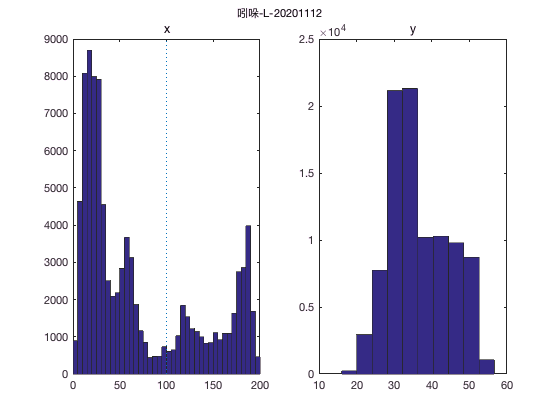

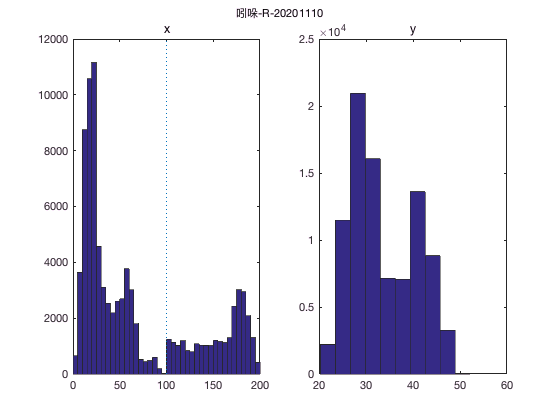

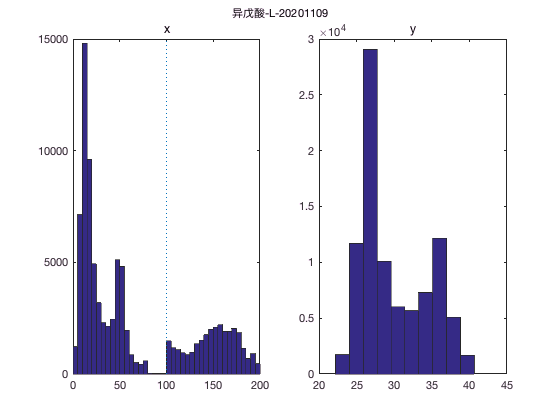

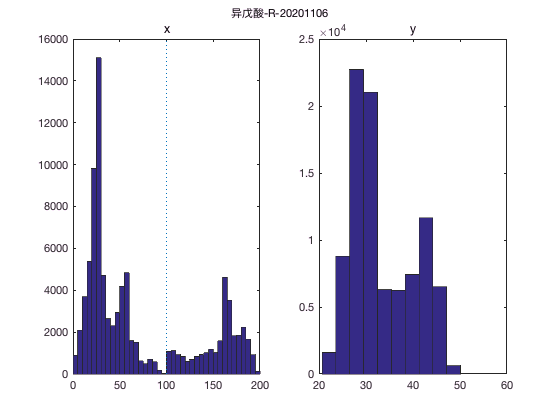

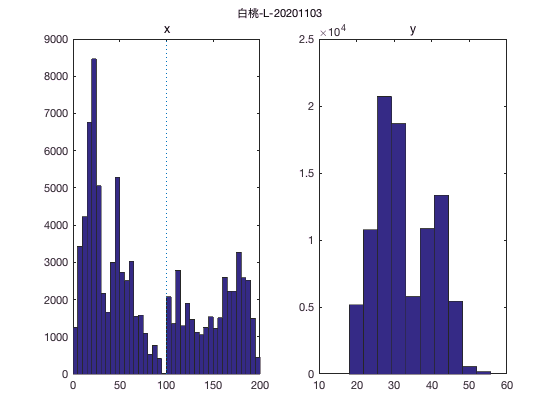

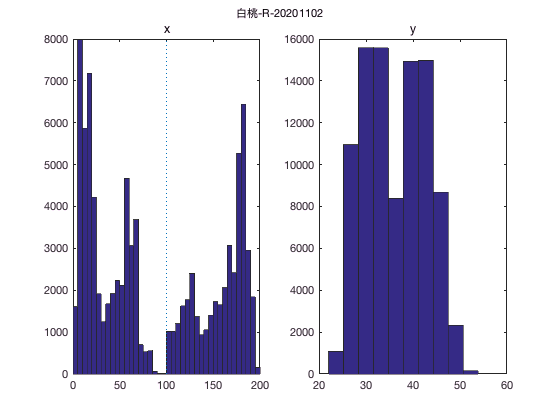

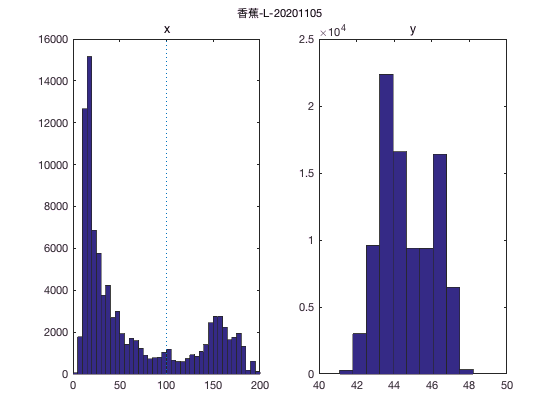

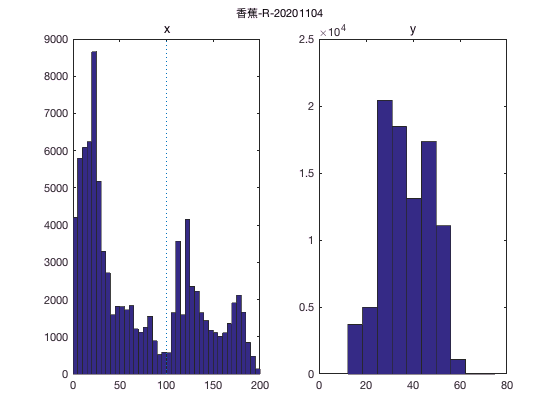

interval=5;
for f=1:length(files)
    data=alldata{f};
    % chisq test
    disp(conditions{f})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        % chit-chisquare test
        [pvalue,st]=chit(data,cutl,cutr)
    end
    figure;
    % x方向的分布
    subplot(1,2,1)
    hist(data(:,2),interval/2:interval:200-interval/2);
    line([100 100],get(gca,'Ylim'),'linestyle',':')
    title('x')
    % y方向的分布
    subplot(1,2,2)
    hist(data(:,3));
    title('y')
    suptitle(conditions{f});
end

## 合并4个条件

tic;
interval=10;
% concatenate all the data
data=cell2mat(alldata');
expect=zeros(3,2);
    % chisq test
    disp('all days');

all days


    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr)
        expect(i/10+1,:)=st.O;
    end

   100   100



pvalue = 0

st =     chi2stat: 7.8286e+04
          df: 1
       edges: [0 100 200]
           O: [487784 247811]
           E: [3.6780e+05 3.6780e+05]


    90   110



pvalue = 0

st =     chi2stat: 8.9840e+04
          df: 1
       edges: [0 100 200]
           O: [482834 229805]
           E: [3.5632e+05 3.5632e+05]


    80   120



pvalue = 0

st =     chi2stat: 1.0384e+05
          df: 1
       edges: [0 100 200]
           O: [473679 207683]
           E: [340681 340681]


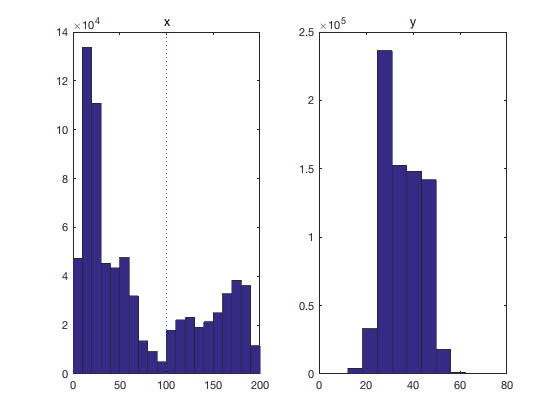


figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')

## 绘制热图

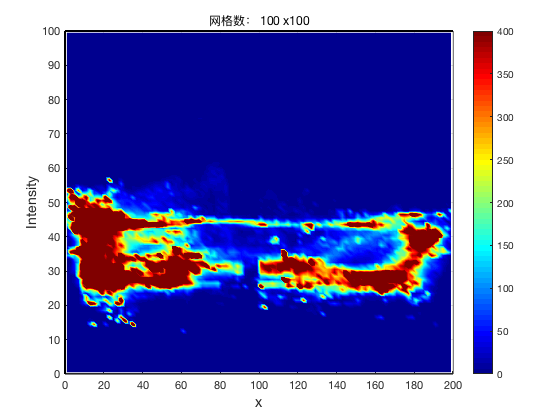

xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title(['网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');

toc;

时间已过 36.211594 秒。


## 合并odor两个条件

吲哚-L-20201112


   100   100



pvalue = 0

st =     chi2stat: 2.1177e+04
          df: 1
       edges: [0 100 200]
           O: [92555 91523]
           E: [1.2206e+05 6.2013e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.6756e+04
          df: 1
       edges: [0 100 200]
           O: [88954 90087]
           E: [1.2131e+05 5.7735e+04]


    80   120



pvalue = 0

st =     chi2stat: 3.1193e+04
          df: 1
       edges: [0 100 200]
           O: [85832 86128]
           E: [1.1955e+05 5.2414e+04]


异戊酸-L-20201109


   100   100



pvalue = 0

st =     chi2stat: 2.3295e+04
          df: 1
       edges: [0 100 200]
           O: [90728 92683]
           E: [1.2162e+05 6.1788e+04]


    90   110



pvalue = 0

st =     chi2stat: 2.6805e+04
          df: 1
       edges: [0 100 200]
           O: [88536 89843]
           E: [1.2086e+05 5.7522e+04]


    80   120



pvalue = 0

st =     chi2stat: 3.0949e+04
          df: 1
       edges: [0 100 200]
           O: [86739 86518]
           E: [1.2045e+05 5.2810e+04]


白桃-L-20201103


   100   100



pvalue = 0

st =     chi2stat: 1.5373e+04
          df: 1
       edges: [0 100 200]
           O: [96927 87159]
           E: [1.2207e+05 6.2016e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.7717e+04
          df: 1
       edges: [0 100 200]
           O: [94478 83732]
           E: [1.2074e+05 5.7467e+04]


    80   120



pvalue = 0

st =     chi2stat: 2.0932e+04
          df: 1
       edges: [0 100 200]
           O: [90355 79045]
           E: [1.1777e+05 5.1634e+04]


香蕉-L-20201105


   100   100



pvalue = 0

st =     chi2stat: 1.1624e+04
          df: 1
       edges: [0 100 200]
           O: [100167 83853]
           E: [1.2203e+05 6.1994e+04]


    90   110



pvalue = 0

st =     chi2stat: 1.4666e+04
          df: 1
       edges: [0 100 200]
           O: [96113 80896]
           E: [1.1993e+05 5.7080e+04]


    80   120



pvalue = 0

st =     chi2stat: 1.9806e+04
          df: 1
       edges: [0 100 200]
           O: [89466 77279]
           E: [1.1592e+05 5.0825e+04]


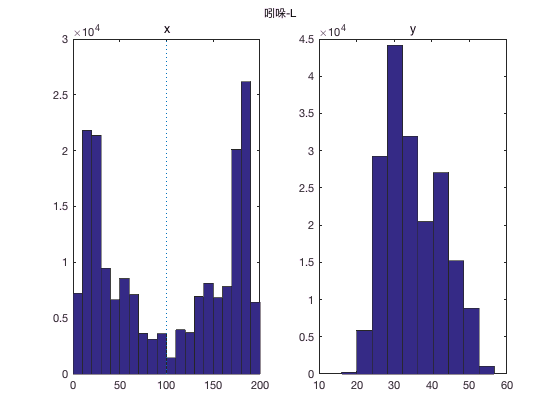

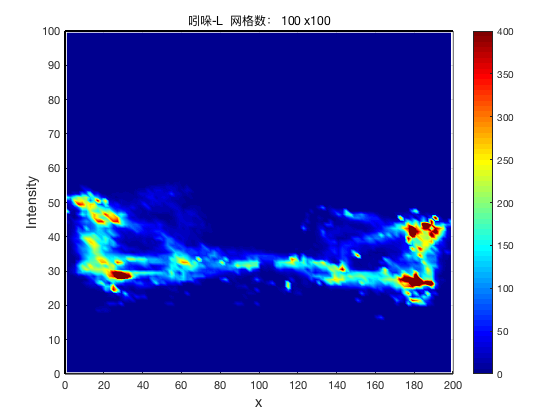

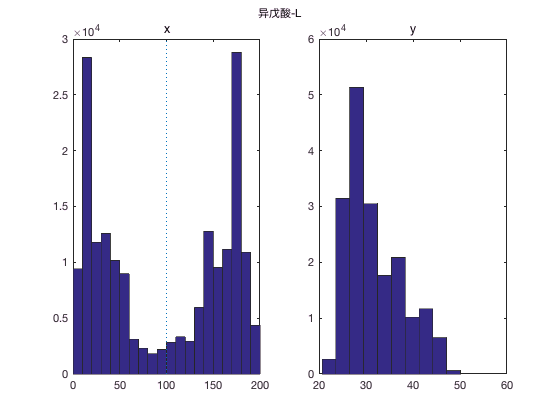

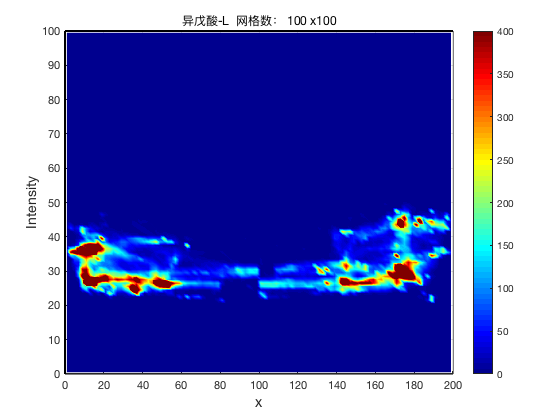

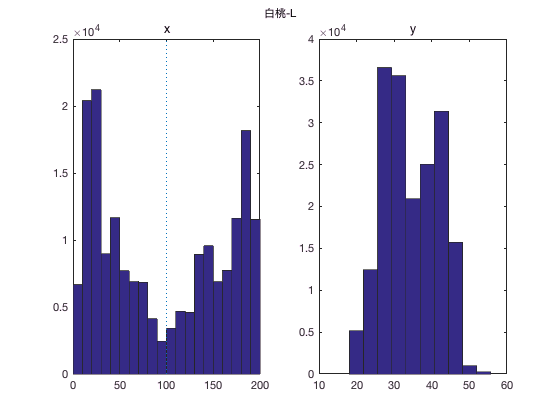

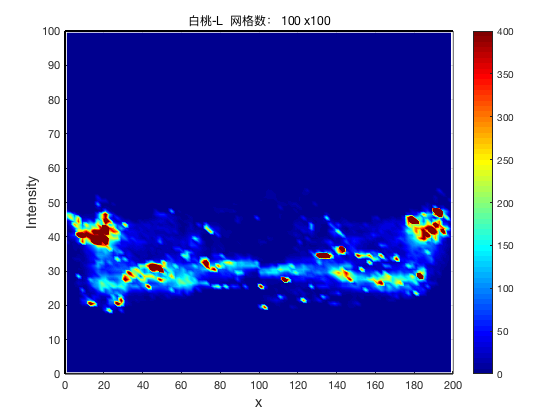

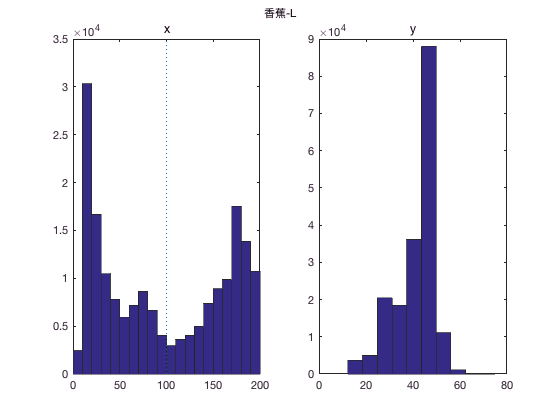

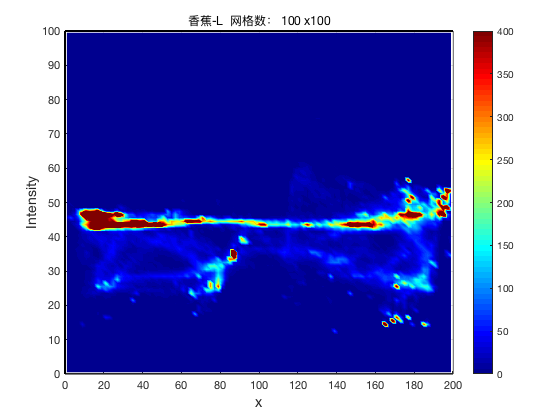

tic;
interval=10;
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1};data];

    % chisq test
    disp(conditions{odor-1})
    for i=0:10:20
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])
        [pvalue,st]=chit(data,cutl,cutr,expect(i/10+1,:))
    end

figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
% 绘制热图
xx=data(:,2);
yy=data(:,3);

% sigma = 0.1;
gridSize = 100;

x=linspace(0,200,gridSize+1);
y=linspace(0,100,gridSize+1);
gridEval = zeros(length(x)-1,length(y)-1);

% 计算每个网格中点的频数
for cnt_x=1:length(x)-1
    for cnt_y=1:length(y)-1
        x_ind=xx>x(cnt_x) & xx<=x(cnt_x+1);                                                    
        xy_ind=yy(x_ind)>y(cnt_y) & yy(x_ind)<=y(cnt_y+1);     
        gridEval(cnt_y, cnt_x)=length(yy(xy_ind));
    end
end

% % 计算每个点处的高斯函数
% for i = 1:length(x)-1
%     for j = 1:length(y)-1
%     %calculate a Gaussian function on the grid with each point in the center and add them up
%         gridEval(j,i) = gridEval(j,i) + sum(exp(-(((x(i)-xx).^2)./(2*sigma.^2) + ((y(j)-yy).^2)./(2*sigma.^2))));       
%     end
% end

% 绘制热图
figure;
surf((x(1:end-1)+ x(2:end))/2,(y(1:end-1)+y(2:end))/2,gridEval); view(2); shading interp;
% 增加z轴会变成三维的
% axis([0 200 0 100 0 100]);
axis([0 200 0 100])
h1 = gca; % 保存句柄，以便后面添加边框
set(gca, 'CLim', [0 400]);
% 添加标注
% title(['平滑散点图, \sigma = ' num2str(sigma) ', 网格数： ' num2str(gridSize) ' x' num2str(gridSize)],'Fontsize',14);
title([t(1:end-9) '  网格数： ' num2str(gridSize) ' x' num2str(gridSize)]);
xlabel('x','Fontsize',14);
ylabel('y','Fontsize',14);

% 添加颜色条
colormap jet
colorbar;
ylabel('Intensity','Fontsize',14);

% 添加黑色的边框
axes(h1);
line(get(gca,'xlim'),repmat(min(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',1);
line(get(gca,'xlim'),repmat(max(get(gca,'ylim')),1,2),'color',[0 0 0],'linewidth',2);
line(repmat(min(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',2);
line(repmat(max(get(gca,'xlim')),1,2),get(gca,'ylim'),'color',[0 0 0],'linewidth',1);

set(gcf,'color',[1 1 1],'paperpositionmode','auto');
end

toc;

时间已过 50.180614 秒。


## 合并odor两个条件的（只取前面一段时间）

   100   100



pvalue = 3.1828e-07

st =     chi2stat: 26.1355
          df: 1
       edges: [0 100 200]
           O: [21617 20567]
           E: [21092 21092]


   100   100



pvalue = 1.4119e-07

st =     chi2stat: 27.7065
          df: 1
       edges: [0 100 200]
           O: [20306 19259]
           E: [1.9782e+04 1.9782e+04]


   100   100



pvalue = 5.9122e-44

st =     chi2stat: 193.3472
          df: 1
       edges: [0 100 200]
           O: [17556 20260]
           E: [18908 18908]


   100   100



pvalue = 1.2461e-05

st =     chi2stat: 19.0913
          df: 1
       edges: [0 100 200]
           O: [20904 21807]
           E: [2.1356e+04 2.1356e+04]


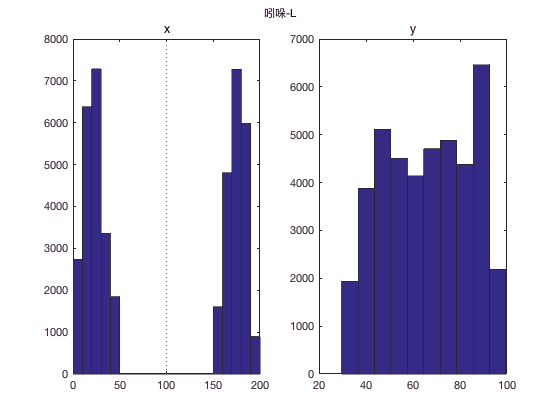

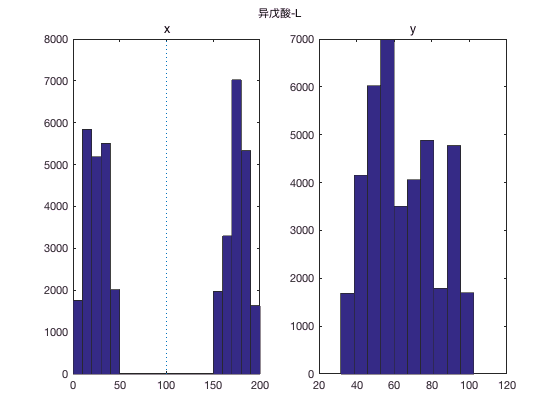

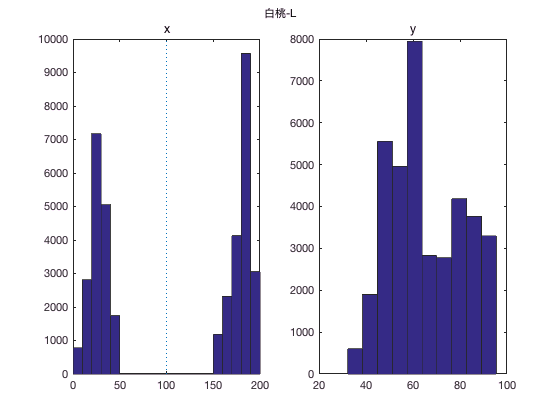

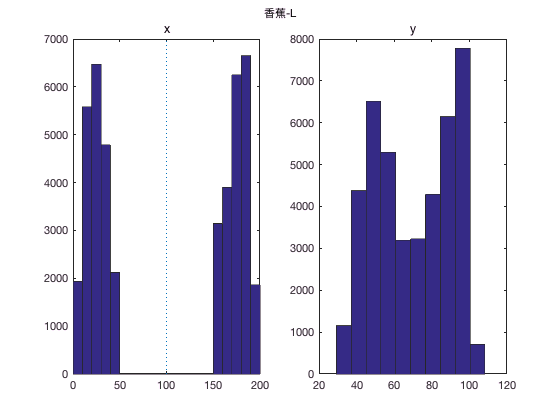

interval=10;
timeint1=30;%start minute
timeint2=50;%stop minute
p1=timeint1*60*1000/40;
p2=timeint2*60*1000/40;
% 1和3合并为1的方向
for odor=2:2:length(conditions)
data=alldata{odor};
data(:,2)=200-data(:,2);
data=[alldata{odor-1}(p1:p2,:);data(p1:p2,:)];
data=data(data(:,2)<=50|data(:,2)>=150,:);
    % chisq test
    for i=0
        cutl=100-i;
        cutr=100+i;
        disp([cutl cutr])

        
        
        
        [pvalue,st]=chit(data,cutl,cutr)
    end
figure;
subplot(1,2,1)
hist(data(:,2),interval/2:interval:200-interval/2);
line([100 100],get(gca,'Ylim'),'linestyle',':')
title('x')
% y方向的分布
subplot(1,2,2)
hist(data(:,3));
title('y')
t=conditions{odor-1};
suptitle(t(1:end-9));
end

## 分时段的分布直方图

吲哚-L-20201112


-------------


100-100


        1008         492
         896         604
         936         564
         913         587
         953         547
         988         512
         992         508
         910         590
         897         603
         932         568
         913         587
        1111         389
         937         563
         897         603
        1087         413
         987         513
         985         515
        1231         269
         981         519
         870         630
         912         588
         979         521
         857         643
         787         713
         986         514
         659         841
        1102         398
        1158         342
        1102         398
         935         565
         796         704
        1060         440
        1057         443
        1192         308
        1222         278
         379        1121
        1155         345
        1036         464
         694         806
         929         571


   4.4918e+03



     0



-------------


-------------


90-110


         978         522
         847         653
         879         621
         863         637
         888         612
         917         583
         949         551
         833         667
         832         668
         843         657
         851         649
        1072         428
         891         609
         784         716
        1060         440
         923         577
         964         536
        1177         323
         935         565
         828         672
         853         647
         938         562
         804         696
         690         810
         870         630
         618         882
        1036         464
        1002         498
        1041         459
         903         597
         771         729
        1038         462
        1019         481
        1159         341
        1205         295
         370        1130
        1119         381
         975         525
         656         844
         880         620


   4.6527e+03



     0



-------------


-------------


80-120


         958         542
         784         716
         772         728
         789         711
         807         693
         848         652
         909         591
         751         749
         762         738
         748         752
         754         746
        1025         475
         844         656
         751         749
        1024         476
         839         661
         926         574
        1121         379
         849         651
         805         695
         790         710
         851         649
         736         764
         631         869
         765         735
         578         922
         978         522
         869         631
         986         514
         883         617
         737         763
        1015         485
         961         539
        1134         366
        1175         325
         364        1136
        1093         407
         935         565
         618         882
         848         652


   4.6429e+03



     0



-------------


-------------


70-130


         934         566
         718         782
         688         812
         709         791
         724         776
         759         741
         865         635
         666         834
         688         812
         666         834
         673         827
         980         520
         803         697
         703         797
         973         527
         757         743
         889         611
        1075         425
         760         740
         775         725
         716         784
         739         761
         657         843
         569         931
         698         802
         534         966
         912         588
         739         761
         940         560
         856         644
         687         813
         991         509
         880         620
        1098         402
        1142         358
         358        1142
        1067         433
         876         624
         576         924
         809         691


   4.8966e+03



     0



-------------


-------------


60-140


         914         586
         668         832
         629         871
         655         845
         658         842
         701         799
         831         669
         604         896
         627         873
         606         894
         613         887
         944         556
         772         728
         671         829
         939         561
         701         799
         858         642
        1029         471
         694         806
         747         753
         659         841
         665         835
         597         903
         521         979
         641         859
         500        1000
         862         638
         584         916
         896         604
         831         669
         602         898
         965         535
         832         668
        1066         434
        1119         381
         352        1148
        1041         459
         839         661
         547         953
         719         781


   4.9961e+03



     0



-------------


-------------


50-150


         893         607
         618         882
         571         929
         606         894
         597         903
         650         850
         805         695
         553         947
         580         920
         553         947
         563         937
         912         588
         748         752
         640         860
         909         591
         650         850
         821         679
         980         520
         638         862
         723         777
         612         888
         599         901
         548         952
         482        1018
         490        1010
         443        1057
         818         682
         534         966
         647         853
         815         685
         571         929
         940         560
         792         708
         870         630
        1101         399
         348        1152
        1022         478
         816         684
         524         976
         683         817


   5.2154e+03



     0



-------------


吲哚-R-20201110


-------------


100-100


         994         506
         832         668
         858         642
         897         603
        1284         216
        1054         446
         793         707
         951         549
        1495           5
         864         636
        1068         432
         995         505
         871         629
        1335         165
         353        1147
        1090         410
        1097         403
        1137         363
        1088         412
        1022         478
         898         602
         615         885
        1090         410
         893         607
         974         526
        1032         468
        1329         171
         788         712
         902         598
        1044         456
         823         677
         985         515
         997         503
        1207         293
        1054         446
        1015         485
         787         713
         918         582
         900         600
         967         533


   5.9714e+03



     0



-------------


-------------


90-110


         935         565
         775         725
         794         706
         842         658
        1255         245
         988         512
         739         761
         892         608
        1352         148
         814         686
        1002         498
         950         550
         811         689
        1326         174
         335        1165
         948         552
        1020         480
         944         556
        1059         441
         964         536
         828         672
         561         939
        1038         462
         855         645
         926         574
         972         528
        1148         352
         713         787
         863         637
         990         510
         771         729
         923         577
         959         541
        1161         339
        1012         488
         983         517
         753         747
         833         667
         863         637
         925         575


   5.2578e+03



     0



-------------


-------------


80-120


         862         638
         717         783
         737         763
         797         703
        1223         277
         898         602
         690         810
         842         658
        1261         239
         780         720
         944         556
         918         582
         784         716
        1321         179
         325        1175
         894         606
         934         566
         872         628
        1039         461
         904         596
         748         752
         501         999
         995         505
         827         673
         861         639
         905         595
        1119         381
         584         916
         808         692
         927         573
         745         755
         871         629
         895         605
        1124         376
         988         512
         958         542
         730         770
         779         721
         825         675
         906         594


   5.0703e+03



     0



-------------


-------------


70-130


         805         695
         668         832
         676         824
         670         830
        1189         311
         828         672
         632         868
         780         720
        1256         244
         743         757
         874         626
         879         621
         761         739
        1315         185
         297        1203
         798         702
         860         640
         826         674
        1018         482
         838         662
         675         825
         454        1046
         954         546
         792         708
         793         707
         840         660
        1092         408
         527         973
         734         766
         861         639
         716         784
         826         674
         833         667
        1092         408
         952         548
         923         577
         712         788
         731         769
         792         708
         872         628


   5.1550e+03



     0



-------------


-------------


60-140


         760         740
         619         881
         622         878
         612         888
        1146         354
         784         716
         559         941
         729         771
        1250         250
         708         792
         808         692
         850         650
         744         756
        1310         190
         282        1218
         760         740
         803         697
         790         710
        1002         498
         780         720
         612         888
         416        1084
         922         578
         759         741
         730         770
         785         715
        1068         432
         485        1015
         675         825
         811         689
         655         845
         787         713
         779         721
        1065         435
         911         589
         897         603
         700         800
         690         810
         763         737
         842         658


   5.6681e+03



     0



-------------


-------------


50-150


         724         776
         571         929
         577         923
         556         944
        1086         414
         675         825
         509         991
         686         814
        1244         256
         679         821
         745         755
         750         750
         726         774
        1304         196
         271        1229
         706         794
         755         745
         759         741
         988         512
         733         767
         545         955
         376        1124
         892         608
         731         769
         668         832
         706         794
        1048         452
         439        1061
         628         872
         764         736
         635         865
         744         756
         733         767
        1042         458
         881         619
         877         623
         687         813
         653         847
         726         774
         809         691


   6.0249e+03



     0



-------------


异戊酸-L-20201109


-------------


100-100


        1033         467
         980         520
        1091         409
         941         559
        1250         250
         992         508
         997         503
        1003         497
        1164         336
         985         515
        1028         472
        1072         428
         992         508
         993         507
        1081         419
        1007         493
        1081         419
         724         776
        1227         273
        1232         268
        1347         153
         926         574
        1174         326
         831         669
        1031         469
         688         812
        1022         478
        1065         435
        1267         233
         774         726
        1227         273
         919         581
         903         597
         971         529
        1038         462
         925         575
         988         512
         985         515
         952         548
         795         705


   3.8676e+03



     0



-------------


-------------


90-110


         947         553
         930         570
        1030         470
         889         611
        1223         277
         933         567
         922         578
         919         581
        1113         387
         926         574
         974         526
        1013         487
         936         564
         937         563
        1016         484
         955         545
        1017         483
         656         844
        1204         296
        1194         306
        1312         188
         885         615
         859         641
         779         721
         960         540
         655         845
         954         546
         988         512
        1227         273
         710         790
         907         593
         884         616
         844         656
         911         589
         990         510
         865         635
         916         584
         932         568
         896         604
         728         772


   3.7544e+03



     0



-------------


-------------


80-120


         752         748
         885         615
         972         528
         844         656
        1206         294
         884         616
         844         656
         844         656
        1051         449
         869         631
         914         586
         952         548
         883         617
         887         613
         953         547
         918         582
         946         554
         602         898
        1179         321
        1171         329
        1264         236
         842         658
         810         690
         737         763
         863         637
         616         884
         892         608
         859         641
        1191         309
         664         836
         809         691
         860         640
         793         707
         856         644
         935         565
         796         704
         846         654
         856         644
         847         653
         667         833


   4.0300e+03



     0



-------------


-------------


70-130


         719         781
         840         660
         921         579
         797         703
        1188         312
         831         669
         787         713
         782         718
        1000         500
         800         700
         845         655
         892         608
         838         662
         663         837
         890         610
         847         653
         887         613
         551         949
        1159         341
        1149         351
        1234         266
         798         702
         780         720
         688         812
         790         710
         563         937
         816         684
         787         713
        1146         354
         618         882
         761         739
         847         653
         734         766
         794         706
         870         630
         731         769
         783         717
         774         726
         803         697
         605         895


   4.0710e+03



     0



-------------


-------------


60-140


         689         811
         777         723
         883         617
         760         740
        1171         329
         726         774
         740         760
         732         768
         958         542
         741         759
         772         728
         841         659
         799         701
         615         885
         846         654
         792         708
         794         706
         513         987
        1142         358
        1130         370
        1210         290
         725         775
         713         787
         636         864
         725         775
         519         981
         760         740
         728         772
        1106         394
         574         926
         724         776
         837         663
         679         821
         733         767
         805         695
         676         824
         729         771
         717         783
         762         738
         550         950


   4.2969e+03



     0



-------------


-------------


50-150


         650         850
         717         783
         835         665
         731         769
        1136         364
         685         815
         692         808
         682         818
         921         579
         696         804
         726         774
         719         781
         763         737
         569         931
         803         697
         744         756
         732         768
         477        1023
        1124         376
        1112         388
        1194         306
         681         819
         665         835
         597         903
         668         832
         479        1021
         710         790
         672         828
        1075         425
         534         966
         691         809
         827         673
         633         867
         678         822
         758         742
         622         878
         686         814
         664         836
         726         774
         502         998


   4.5750e+03



     0



-------------


异戊酸-R-20201106


-------------


100-100


        1161         339
        1190         310
         868         632
        1048         452
         915         585
        1035         465
        1076         424
        1127         373
        1099         401
        1021         479
        1099         401
        1058         442
        1090         410
         851         649
        1106         394
        1101         399
         885         615
        1138         362
         738         762
        1102         398
         966         534
         975         525
        1130         370
        1171         329
        1319         181
         804         696
        1143         357
         903         597
        1207         293
        1022         478
        1074         426
        1067         433
        1041         459
         947         553
         822         678
        1038         462
         902         598
         832         668
         693         807
         989         511


   7.8619e+03



     0



-------------


-------------


90-110


        1148         352
        1154         346
         793         707
         989         511
         822         678
         889         611
         992         508
        1058         442
         988         512
         940         560
        1042         458
         988         512
        1032         468
         730         770
         947         553
        1021         479
         812         688
        1028         472
         678         822
         994         506
         879         621
         915         585
        1077         423
        1075         425
        1292         208
         748         752
        1105         395
         804         696
        1187         313
         918         582
        1004         496
        1001         499
         945         555
         872         628
         762         738
         924         576
         800         700
         762         738
         650         850
         940         560


   7.5674e+03



     0



-------------


-------------


80-120


         924         576
        1121         379
         747         753
         920         580
         759         741
         814         686
         921         579
         999         501
         898         602
         869         631
         978         522
         953         547
         979         521
         659         841
         858         642
         967         533
         765         735
         953         547
         636         864
         941         559
         818         682
         867         633
        1037         463
        1008         492
        1173         327
         708         792
        1088         412
         740         760
        1174         326
         823         677
         971         529
         966         534
         868         632
         811         689
         717         783
         840         660
         723         777
         699         801
         629         871
         910         590


   7.7541e+03



     0



-------------


-------------


70-130


         912         588
        1088         412
         700         800
         858         642
         697         803
         756         744
         878         622
         942         558
         811         689
         805         695
         913         587
         924         576
         938         562
         600         900
         787         713
         921         579
         724         776
         875         625
         600         900
         888         612
         771         729
         814         686
         984         516
         945         555
         853         647
         672         828
        1073         427
         680         820
        1162         338
         774         726
         933         567
         932         568
         787         713
         744         756
         676         824
         751         749
         630         870
         644         856
         589         911
         878         622


   7.4492e+03



     0



-------------


-------------


60-140


         903         597
        1067         433
         658         842
         812         688
         651         849
         709         791
         836         664
         903         597
         749         751
         760         740
         862         638
         899         601
         900         600
         556         944
         734         766
         885         615
         696         804
         823         677
         572         928
         859         641
         730         770
         773         727
         933         567
         898         602
         816         684
         646         854
        1066         434
         625         875
        1151         349
         732         768
         900         600
         902         598
         726         774
         701         799
         651         849
         693         807
         578         922
         599         901
         562         938
         854         646


   7.1023e+03



     0



-------------


-------------


50-150


         895         605
        1047         453
         628         872
         779         721
         614         886
         673         827
         800         700
         874         626
         620         880
         726         774
         823         677
         879         621
         872         628
         519         981
         698         802
         860         640
         664         836
         788         712
         550         950
         829         671
         702         798
         744         756
         900         600
         860         640
         785         715
         622         878
        1061         439
         585         915
        1140         360
         700         800
         859         641
         879         621
         684         816
         671         829
         630         870
         635         865
         529         971
         562         938
         542         958
         834         666


   7.0368e+03



     0



-------------


白桃-L-20201103


-------------


100-100


        1053         447
         654         846
         651         849
        1059         441
        1061         439
         581         919
         945         555
         208        1292
         902         598
         357        1143
         986         514
         461        1039
        1450          50
        1005         495
        1011         489
        1500           0
         696         804
         928         572
         938         562
        1127         373
         863         637
         362        1138
         859         641
         653         847
         432        1068
        1499           1
         471        1029
         463        1037
        1500           0
         810         690
         441        1059
         687         813
        1094         406
         767         733
         806         694
        1017         483
         376        1124
         577         923
         656         844
         743         757


   1.8633e+04



     0



-------------


-------------


90-110


        1016         484
         618         882
         610         890
         982         518
        1017         483
         519         981
         887         613
         184        1316
         871         629
         332        1168
         939         561
         424        1076
        1413          87
         868         632
        1006         494
        1500           0
         662         838
         895         605
         905         595
        1002         498
         822         678
         304        1196
         841         659
         607         893
         370        1130
        1466          34
         464        1036
         458        1042
        1500           0
         679         821
         366        1134
         652         848
        1018         482
         708         792
         753         747
         979         521
         348        1152
         506         994
         569         931
         643         857


   1.9403e+04



     0



-------------


-------------


80-120


         994         506
         568         932
         573         927
         906         594
         983         517
         464        1036
         849         651
         166        1334
         828         672
         319        1181
         897         603
         407        1093
        1402          98
         833         667
        1002         498
        1500           0
         615         885
         878         622
         874         626
         939         561
         766         734
         274        1226
         815         685
         498        1002
         307        1193
        1451          49
         461        1039
         454        1046
        1500           0
         651         849
         349        1151
         626         874
         955         545
         590         910
         699         801
         909         591
         316        1184
         432        1068
         558         942
         549         951


   1.9433e+04



     0



-------------


-------------


70-130


         972         528
         533         967
         530         970
         853         647
         953         547
         409        1091
         797         703
         150        1350
         800         700
         309        1191
         825         675
         379        1121
        1397         103
         810         690
         998         502
        1500           0
         594         906
         848         652
         835         665
         786         714
         680         820
         246        1254
         791         709
         402        1098
         269        1231
        1439          61
         459        1041
         450        1050
        1500           0
         607         893
         341        1159
         594         906
         866         634
         517         983
         668         832
         838         662
         292        1208
         391        1109
         431        1069
         483        1017


   1.9542e+04



     0



-------------


-------------


60-140


         950         550
         492        1008
         481        1019
         797         703
         928         572
         370        1130
         760         740
         134        1366
         776         724
         301        1199
         762         738
         358        1142
        1374         126
         789         711
         995         505
        1500           0
         330        1170
         638         862
         797         703
         722         778
         637         863
         224        1276
         773         727
         364        1136
         247        1253
        1430          70
         457        1043
         445        1055
        1500           0
         583         917
         334        1166
         557         943
         732         768
         465        1035
         650         850
         797         703
         278        1222
         363        1137
         406        1094
         435        1065


   1.9706e+04



     0



-------------


-------------


50-150


         932         568
         457        1043
         451        1049
         760         740
         900         600
         338        1162
         725         775
         123        1377
         741         759
         296        1204
         726         774
         340        1160
        1032         468
         777         723
         989         511
        1500           0
         323        1177
         603         897
         773         727
         688         812
         606         894
         199        1301
         756         744
         317        1183
         227        1273
        1422          78
         455        1045
         442        1058
        1500           0
         559         941
         329        1171
         519         981
         609         891
         418        1082
         556         944
         755         745
         263        1237
         335        1165
         389        1111
         399        1101


   1.8842e+04



     0



-------------


白桃-R-20201102


-------------


100-100


        7969       14531
        7845       14655
       10132       12368
       10094       12406
        1727         925



   1.5681e+03



     0



-------------


-------------


90-110


        7565       14935
        6974       15526
        9760       12740
        9848       12652
        1702         950



   1.9846e+03



     0



-------------


-------------


80-120


        6977       15523
        6718       15782
        9068       13432
        9322       13178
        1465        1187



   1.5011e+03



  9.8813e-324



-------------


-------------


70-130


        6573       15927
        6581       15919
        8297       14203
        8877       13623
        1414        1238



   1.2708e+03



  7.2372e-274



-------------


-------------


60-140


        6402       16098
        6469       16031
        8033       14467
        8515       13985
        1374        1278



   1.1252e+03



  2.5526e-242



-------------


-------------


50-150


        6250       16250
        6356       16144
        7739       14761
        8063       14437
        1334        1318



  947.4977



  8.5106e-204



-------------


香蕉-L-20201105


-------------


100-100


       15328        7172
       16629        5871
       16333        6167
       13995        8505
        2064        1763



   1.2726e+03



  2.9447e-274



-------------


-------------


90-110


       14416        8084
       15854        6646
       15337        7163
       13013        9487
        1837        1990



   1.3732e+03



  4.5541e-296



-------------


-------------


80-120


       13548        8952
       15153        7347
       14173        8327
       12261       10239
        1644        2183



   1.3332e+03



  2.0903e-287



-------------


-------------


70-130


       12742        9758
       14283        8217
       13411        9089
       11563       10937
        1550        2277



   1.1631e+03



  1.6133e-250



-------------


-------------


60-140


       12012       10488
       13800        8700
       12834        9666
       11013       11487
        1481        2346



   1.1586e+03



  1.4732e-249



-------------


-------------


50-150


       11357       11143
       13171        9329
       12170       10330
       10412       12088
        1424        2403



   1.0732e+03



  4.9655e-231



-------------


香蕉-R-20201104


-------------


100-100


       12940        9560
       12282       10218
       14529        7971
       16559        5941
         190           0



   2.1798e+03



     0



-------------


-------------


90-110


       11990       10510
       11389       11111
       13860        8640
       15779        6721
         190           0



   2.3037e+03



     0



-------------


-------------


80-120


       11164       11336
       10621       11879
       13293        9207
       15150        7350
         190           0



   2.4857e+03



     0



-------------


-------------


70-130


       10322       12178
       10039       12461
       12709        9791
       14577        7923
         190           0



   2.6263e+03



     0



-------------


-------------


60-140


        9555       12945
        9557       12943
       12076       10424
       14102        8398
         190           0



   2.7713e+03



     0



-------------


-------------


50-150


        8878       13622
        9094       13406
       11623       10877
       13470        9030
         190           0



   2.7720e+03



     0



-------------


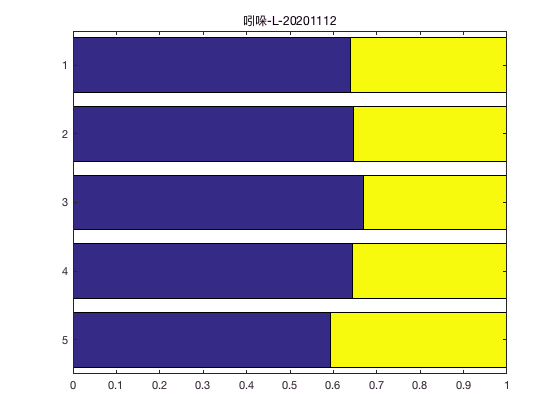

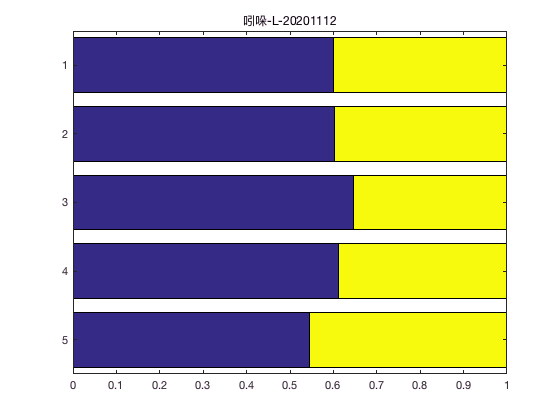

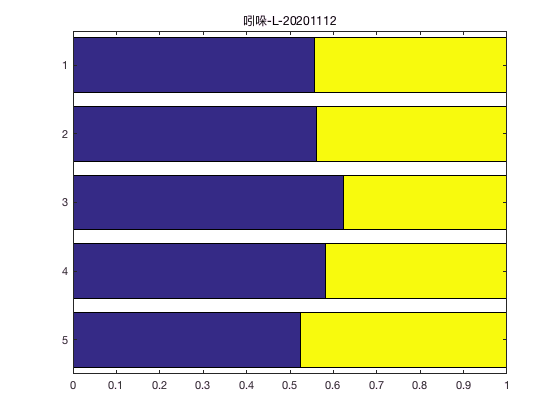

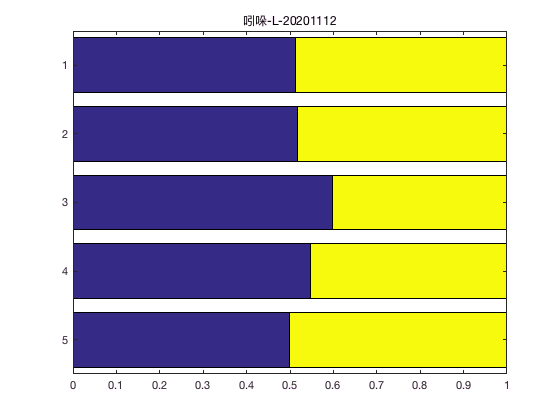

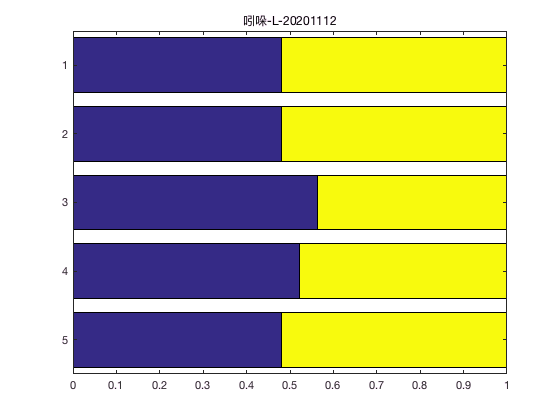

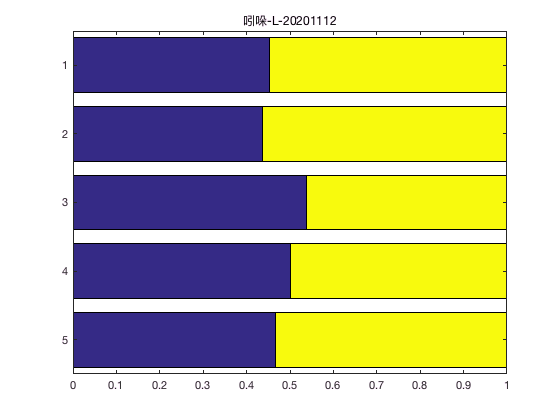

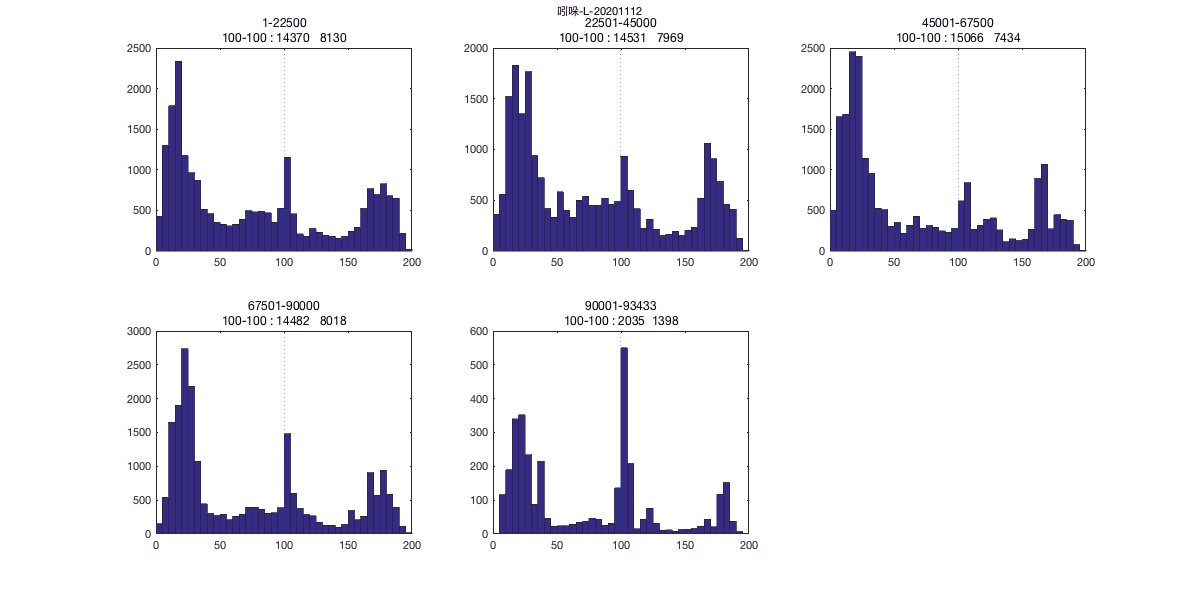

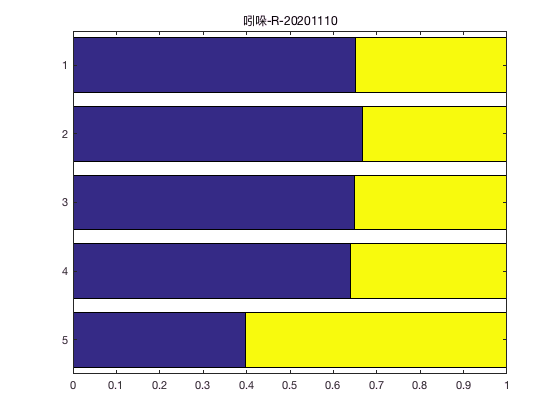

timeint=1;%minute
p=round(timeint*60*1000/40);
interval=5;
% plot each day
for f=1:length(files)
    data=alldata{f};
    l=length(data(:,2));
    plots=ceil(l/p);

    disp('===========================')
    disp(conditions{f})
    disp('===========================')
    for j=0:10:50
        timelab=zeros(1,l);
        leftright=timelab;
        cutl=100-j;
        cutr=100+j;
        leftright(data(:,2)<cutl)=1;
        leftright(data(:,2)>cutl)=2;
        for i=1:plots
            timelab(p*(i-1)+1:min(p*i,l))=i;                     
        end
        timelab(leftright==0)=[];
        leftright(leftright==0)=[];
        [tbl,chi2,pvalue] = crosstab(timelab,leftright);
        disp('-------------')
        disp([num2str(cutl) '-' num2str(cutr)])
        disp(tbl)
        disp(chi2)
        disp(pvalue)
        disp('-------------')
        % barplot
        percenttbl=tbl./sum(tbl,2);
        figure;
        barh(percenttbl,'stack')
        set(gca,'YDir','reverse')
        title(conditions{f})  
    end
    
    figure;
    set(gcf,'position',[1280,720,ceil(plots/2)*400,2*300]);
    % subplot each bin
    for i=1:plots
        subplot(2,ceil(plots/2),i)
        hist(data(p*(i-1)+1:min(p*i,l),2),interval/2:interval:200-interval/2)
        line([100 100],get(gca,'Ylim'),'linestyle',':')
%         disp('-------------')
%         disp([num2str(p*(i-1)+1) '-' num2str(min(p*i,l))])
%         
            % chisq test
        for j=0%:10:20
            cutl=100-j;
            cutr=100+j;
%             disp([cutl cutr])
            [pvalue,st]=chit(data(p*(i-1)+1:min(p*i,l),:),cutl,cutr);
        end
%         disp('-------------')
        
        title({[num2str(p*(i-1)+1) '-' num2str(min(p*i,l))];[num2str(cutl) '-' num2str(cutr) ' : ' num2str(st.O)]})
    end
    suptitle({conditions{f};''});
end